# Generalization of the reduction dichromacy solver method 

The main method solves perfectly in the absence of noise, or equivalently in the absence of any differences in the fundamentals between individuals.  Because of differences in the inert pigments of the lens and macula, and perhaps other slight differences, the cone fundamentals between trichromats and dichromats will differ.

This script simulates the expected differences in cone fundamentals based on variations in these inert pigments. 

This script is stochastic - run it several times to sample the likely difference. Most of the time the reconstruction is very satisfactory. 

However, it can fail. We need to think a bit more where this comes from. Probably because randn gives very big numbers sometimes.

Requires ISETBio and ISETCam.  ISETBio includes some BrainardLabToolbox routines.

Created By Thomas Goossens  2023

close all;
nbWavelengths=100;
wl_start_nm = 400;

% Helper function to normalize data
% Could use ieScale()
% n = @(A)A/max(abs(A(:))); % normalize

## Generate LMS cones for three different individuals

We generate three individuals with different LMS cones.

coneParams = DefaultConeParams('cie_asano');
% wl start , stepsize , number of steps
S = [wl_start_nm 1 301];
lambda=SToWls(S);

% Individual 1
coneParams.indDiffParams.dmac=0;
coneParams.indDiffParams.dlens=0;
LMS(:,:,1) = ComputeObserverFundamentals(coneParams,S)';

% Individual 2
coneParams.indDiffParams.dmac=50;
 coneParams.indDiffParams.dlens=50;
LMS(:,:,2) = ComputeObserverFundamentals(coneParams,S)';

% Individual 3
coneParams.indDiffParams.dmac=100;
coneParams.indDiffParams.dlens=100; 
LMS(:,:,3)= ComputeObserverFundamentals(coneParams,S)';


## Organize L M and S cones in separate matrices.

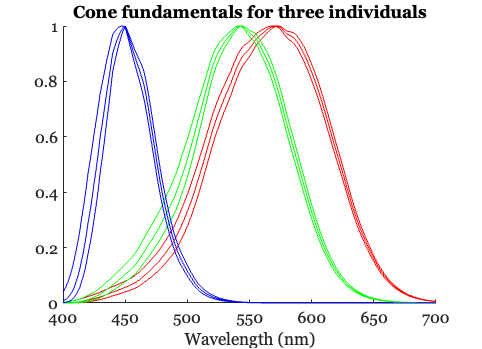

lcones = zeros(size(LMS,1),size(LMS,3));
mcones = zeros(size(LMS,1),size(LMS,3));
scones = zeros(size(LMS,1),size(LMS,3));
for i=1:3
    lcones(:,i)=LMS(:,1,i);
    mcones(:,i)=LMS(:,2,i);
    scones(:,i)=LMS(:,3,i);
end

%% plot the three L, M and S cones
ieNewGraphWin; hold on
plot(lambda,lcones,'r')
plot(lambda,mcones,'g')
plot(lambda,scones,'b')
title('Cone fundamentals for three individuals')
xlabel('Wavelength (nm)')   
exportgraphics(gcf,'fig/cones.pdf')

## Construct the color matching functions for three types of dichromats (leaving out one of the cones)

For each type we leave out one cone fundamental and apply a multiplication with a random 2x2 matrix (we can choose a more relistic one later)

%Protanope (Leave out L)
Cp=rand(2); 
P=[mcones(:,1) scones(:,1)]*Cp;
% Deuteranope   (leave out M)
Cd=rand(2);
D=[lcones(:,2) scones(:,2)]*Cd;
% Tritanope (leave out S)
Ct=rand(2);
T=[lcones(:,3) mcones(:,3)]*Ct;

noiselevel =0* 3e-3

noiselevel = 0

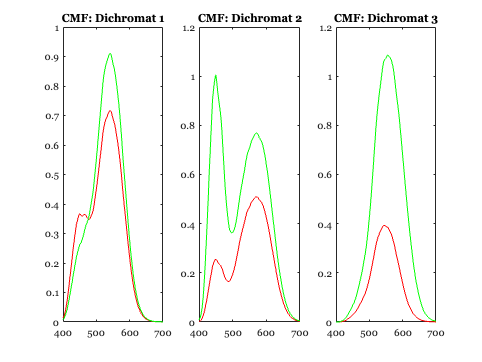

P = P + noiselevel*randn(size(P));
D = D + noiselevel*randn(size(D));
T = T + noiselevel*randn(size(T));
figure; tiledlayout(1,3);
nexttile; plot(lambda,P)
title('CMF: Dichromat 1')
nexttile; plot(lambda,D)
title('CMF: Dichromat 2')
nexttile; plot(lambda,T)
title('CMF: Dichromat 3')

## The null space is empty

There is no intersection between the subspaces because the individuals do not share a cone fundamental exactly. We will use the SVD to approximate it.

nullspace=null([P D]) % is empty


nullspace =

  4×0 empty double matrix



## Estimate L cone fundamentals

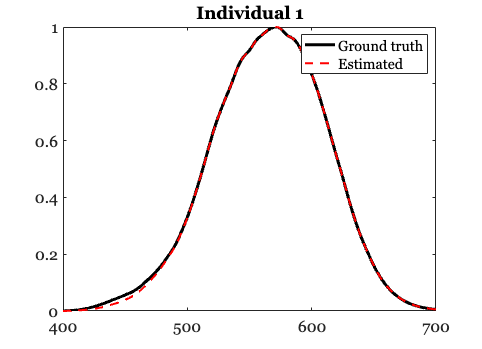

[U,S,V] = svd([D T]);

% Closest to the null
V4=V(:,4);

% We can formulate an estimate in both subspaces(column spaces) 
L_estimate_1 = D*V4(1:2); %individual 1
L_estimate_2 = T*V4(3:4); %individual 2

ieNewGraphWin; 
tiledlayout(2,1); 
plot(lambda,lcones(:,2),'k-','linewidth',3); hold on;
plot(lambda,abs(L_estimate_1)/max(abs(L_estimate_1)),'r--','linewidth',2)
legend({'Ground truth','Estimated'})
title('Individual 1')

nexttile;

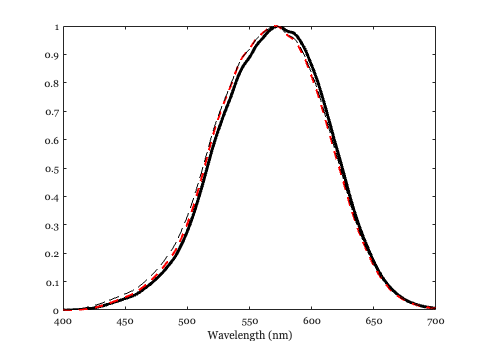

plot(lambda,lcones(:,3),'k-','linewidth',3); hold on;
plot(lambda,abs(L_estimate_2)/max(abs(L_estimate_2)),'r--','linewidth',2)
plot(lambda,lcones(:,2),'k--')
xlabel('Wavelength (nm)')

## Estimate M cone fundamentals

[U,S,V] = svd([P T]);
V4=V(:,4)

V4 =    -0.2874
    0.4433
   -0.8409
    0.1174


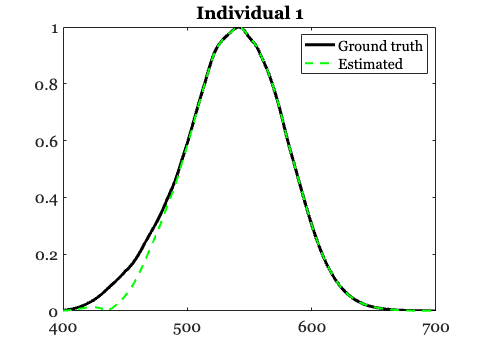

% We can formulate an estimate in both subspaces(column spaces) 
M_estimate_1 = P*V4(1:2); %individual 1
M_estimate_2 = T*V4(3:4); %individual 2

ieNewGraphWin;
tiledlayout(2,1);
plot(lambda,mcones(:,1),'k-','linewidth',3); hold on;
plot(lambda,abs(M_estimate_1)/max(abs(M_estimate_1)),'g--','linewidth',2)
legend({'Ground truth','Estimated'})
title('Individual 1')

nexttile;

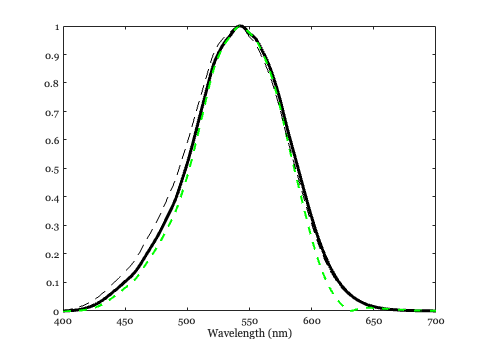

plot(lambda,mcones(:,2),'k-','linewidth',3); hold on;
plot(lambda,abs(M_estimate_2)/max(abs(M_estimate_2)),'g--','linewidth',2)
plot(lambda,mcones(:,1),'k--')
xlabel('Wavelength (nm)')

## Estimate S cone fundamentals

[U,S,V] = svd([P D]);
V4=V(:,4)

V4 =    -0.7345
    0.5751
   -0.2997
    0.2000


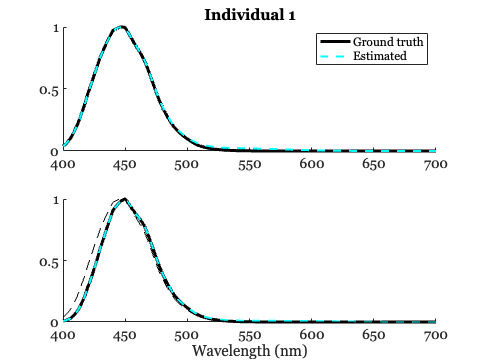

% We can formulate an estimate in both subspaces(column spaces) 
S_estimate_1 = P*V4(1:2); %individual 1
S_estimate_2 = D*V4(3:4); %individual 2

figure; hold on;
subplot(211); hold on
plot(lambda,scones(:,1),'k-','linewidth',3)
plot(lambda,abs(S_estimate_1)/max(abs(S_estimate_1)),'c--','linewidth',2)
legend('Ground truth','Estimated')
title('Individual 1')

subplot(212); hold on
plot(lambda,scones(:,2),'k-','linewidth',3)
plot(lambda,abs(S_estimate_2)/max(abs(S_estimate_2)),'c--','linewidth',2)
plot(lambda,scones(:,1),'k--')
xlabel('Wavelength (nm)')   

## One plot

[U,S,V] = svd([P D]);
V4=V(:,4)

V4 =    -0.7345
    0.5751
   -0.2997
    0.2000


% We can formulate an estimate in both subspaces(column spaces) 
S_estimate_1 = P*V4(1:2); %individual 1
S_estimate_2 = D*V4(3:4); %individual 2

figure; hold on;
S

S =    14.2759         0         0         0
         0    3.7682         0         0
         0         0    1.4825         0
         0         0         0    0.1036
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


href=plot(lambda,lcones(:,2),'k:','linewidth',2)

href =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [400 401 402 403 404 405 406 407 408 409 410 411 412 413 414 415 416 417 418 419 420 421 422 423 424 425 426 427 428 429 430 431 432 433 434 435 436 437 438 439 440 441 442 443 444 445 446 447 448 449 450 451 452 453 454 455 456 … ]
              YData: [3.4797e-04 4.3670e-04 5.4657e-04 6.8306e-04 8.5343e-04 0.0011 0.0013 0.0016 0.0019 0.0023 0.0028 0.0032 0.0037 0.0043 0.0050 0.0058 0.0064 0.0072 0.0081 0.0091 0.0103 0.0111 0.0121 0.0131 0.0143 0.0155 0.0167 0.0179 0.0193 … ]

  Show all properties

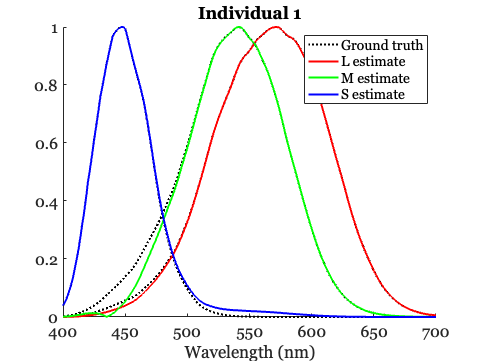

plot(lambda,mcones(:,1),'k:','linewidth',2);
plot(lambda,scones(:,1),'k:','linewidth',2);
hL=plot(lambda,abs(L_estimate_1)/max(abs(L_estimate_1)),'r-','linewidth',2);
hM=plot(lambda,abs(M_estimate_1)/max(abs(M_estimate_1)),'g-','linewidth',2);
hS=plot(lambda,abs(S_estimate_1)/max(abs(S_estimate_1)),'b-','linewidth',2);

legh=legend([href, hL hM hS],'Ground truth','L estimate','M estimate','S estimate');
title('Individual 1')
xlabel('Wavelength (nm)')

exportgraphics(gcf,'fig/individual1.pdf')


figure; hold on;

href=plot(lambda,lcones(:,3),'k:','linewidth',2);
plot(lambda,mcones(:,2),'k:','linewidth',2);
plot(lambda,scones(:,2),'k:','linewidth',2);
hL=plot(lambda,abs(L_estimate_2)/max(abs(L_estimate_2)),'r-','linewidth',2);
hM=plot(lambda,abs(M_estimate_2)/max(abs(M_estimate_2)),'g-','linewidth',2);
hS=plot(lambda,abs(S_estimate_2)/max(abs(S_estimate_2)),'b-','linewidth',2);

title('Individual 2')
xlabel('Wavelength (nm)')
legh=legend([href, hL hM hS],'Ground truth','L estimate','M estimate','S estimate')

legh =   Legend (Ground truth, L estimate, M estimate, S estimate) with properties:

         String: {'Ground truth'  'L estimate'  'M estimate'  'S estimate'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 14.4000
       Position: [0.6696 0.7417 0.2214 0.1655]
          Units: 'normalized'

  Show all properties


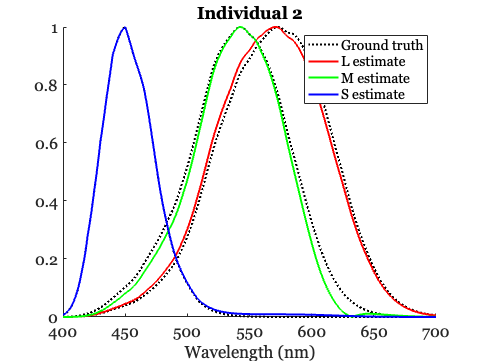

exportgraphics(gcf,'fig/individual2.pdf')

## Just try a brute force solver

% Structure of the unknowns
% 
% C=[0 0  x x   x x 
%    x x  0 0   x x 
%    x x  x x   0 0  ]
%
% known   = unknownLMS*unknownC
% [P D T] = [l m s]*C
% [P D T] = [x_1 X_n+1 x_2*n+1
%            x_2 ..           ]*C
%

% Reduction dichromatcy assumption: shared fundamentals are identical
% Protanope (Leave out L)
Cp = rand(2); 
P  = [mcones(:,1) scones(:,1)]*Cp;

% Deuteranope   (leave out M)
Cd=rand(2);
D=[lcones(:,1) scones(:,1)]*Cd;

% Tritanope (leave out S)
Ct=rand(2);
T=[lcones(:,1) mcones(:,1)]*Ct;


% LMS has 3*N unknowns
nLMS = numel(LMS(:,:,1))

nLMS = 903

nbx = nLMS+4*3; % total number of unknowns
x = abs(randn(1,nbx));

%
N = size(LMS,1)

N = 301


% Initalizing the problem well makes it converge
x(1:3*N) = reshape(LMS(:,:,1),[3*N 1])

x =     0.0025    0.0030    0.0034    0.0040    0.0046    0.0053    0.0060    0.0068    0.0078    0.0088    0.0100    0.0110    0.0121    0.0133    0.0146    0.0160    0.0172    0.0186    0.0200    0.0216    0.0234    0.0247    0.0261    0.0276    0.0292    0.0309    0.0325    0.0341    0.0358    0.0377    0.0398    0.0415    0.0433    0.0453    0.0473    0.0494    0.0513    0.0532    0.0552    0.0573    0.0595    0.0611    0.0629    0.0647    0.0667    0.0687    0.0707    0.0727    0.0749    0.0772



LMS_unknown = @(x) [x(1:N)' x(N+1:2*N)' x(2*N+1:3*N)']

LMS_unknown = function_handle with value:
    @(x)[x(1:N)',x(N+1:2*N)',x(2*N+1:3*N)']


%xc = x(3*N+1:end);
%C_unknown = @(xc) [0 0     0      xc(5) 0 xc(7)   xc(9) xc(11) 0
%           0 xc(1) xc(3)  0     0   0     xc(10) xc(12) 0
%         0 xc(2) xc(4)  xc(6) 0 xc(8)   0 0 0  ]

C_unknown = @(xc) [ 0     0      xc(5)  xc(7)   xc(9) xc(11)
                   xc(1) xc(3)  0       0     xc(10) xc(12) 
                   xc(2) xc(4)  xc(6) xc(8)   0 0  ]

C_unknown = function_handle with value:
    @(xc)[0,0,xc(5),xc(7),xc(9),xc(11);xc(1),xc(3),0,0,xc(10),xc(12);xc(2),xc(4),xc(6),xc(8),0,0]



PDT = [P D T]

PDT =     0.0129    0.0112    0.0129    0.0197    0.0028    0.0032
    0.0152    0.0132    0.0152    0.0232    0.0032    0.0038
    0.0179    0.0156    0.0180    0.0274    0.0037    0.0044
    0.0211    0.0184    0.0211    0.0322    0.0043    0.0051
    0.0248    0.0216    0.0248    0.0378    0.0050    0.0059
    0.0292    0.0254    0.0292    0.0444    0.0058    0.0069
    0.0335    0.0292    0.0335    0.0509    0.0066    0.0079
    0.0384    0.0335    0.0385    0.0584    0.0075    0.0089
    0.0441    0.0384    0.0441    0.0670    0.0085    0.0102
    0.0506    0.0441    0.0506    0.0768    0.0097    0.0116


F = @(x) norm(PDT-LMS_unknown(x)*C_unknown(x(3*N+1:end)))

F = function_handle with value:
    @(x)norm(PDT-LMS_unknown(x)*C_unknown(x(3*N+1:end)))



% Force LMS functions to be nonnegative
% Aineq = diag([ones(1,3*N) ones(1,nbx-3*N)]);
% bineq = ones(nbx,1);;

xsol = fmincon(F,x)


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



xsol =    -0.0024   -0.0029   -0.0034   -0.0041   -0.0049   -0.0058   -0.0067   -0.0078   -0.0090   -0.0104   -0.0120   -0.0135   -0.0152   -0.0171   -0.0192   -0.0216   -0.0236   -0.0258   -0.0282   -0.0307   -0.0334   -0.0354   -0.0375   -0.0397   -0.0419   -0.0442   -0.0461   -0.0481   -0.0501   -0.0521   -0.0540   -0.0552   -0.0563   -0.0573   -0.0584   -0.0595   -0.0602   -0.0610   -0.0617   -0.0623   -0.0628   -0.0623   -0.0617   -0.0609   -0.0599   -0.0589   -0.0576   -0.0562   -0.0546   -0.0527



maxnorm = @(A) A*diag(max(A).^-1)

maxnorm = function_handle with value:
    @(A)A*diag(max(A).^-1)


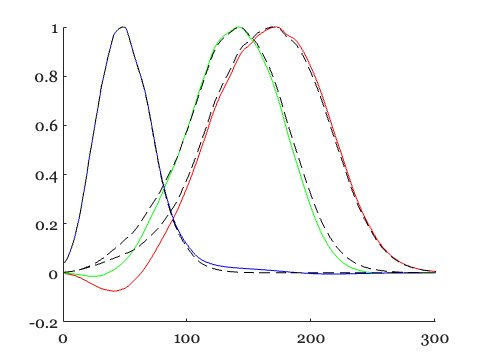

figure; hold on
plot(maxnorm(LMS_unknown(xsol)))
plot(LMS(:,:,1),'k--')